# Systems of ODEs

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

When modeling complex real-world systems, we often encounter situations where multiple dependent variables are interconnected and change over time. This leads us to **systems of differential equations**. In this script, we'll learn how to solve systems of linear, homogeneous, first-order differential equations using eigenvalues and eigenvectors, with applications in epidemiology and structural engineering.

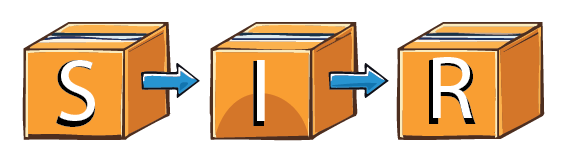

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View** tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**. Alternately, select **Hide Code** using the icon   at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2 hour online tutorial that teaches the essentials of MATLAB.

 For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

The   and  icons refer to two different types of interactive activities that you will find in this script. The   usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## Background Knowledge

This script expects you to know the basics of matrices. If you are not comfortable with representing a system of equations in matrix form or computing eigenvalues and eigenvectors, please start by working through the [Matrix Methods of Linear Algebra](https://www.mathworks.com/matlabcentral/fileexchange/94730-matrix-methods-of-linear-algebra). There are also a few facts about exponentials that will prove relevant. First, the fact that the exponential function is never $0$. Second, it is helpful to recognize that complex exponentials are related to sines and cosines by Euler's identity: $e^{i\theta} = \cos(\theta) + i\sin(\theta)$, and thus are bounded in magnitude. 

## Systems of Linear ODEs

### Matrix Form of Systems

A system of linear, homogeneous, first-order differential equations can be written in the following form:


$$\frac{dx_1}{dt} = a_{11}x_1 + a_{12}x_2 + \cdots + a_{1n}x_n$$



$$\frac{dx_2}{dt} = a_{21}x_1 + a_{22}x_2 + \cdots + a_{2n}x_n$$



$$\vdots$$



$$\frac{dx_n}{dt} = a_{n1}x_1 + a_{n2}x_2 + \cdots + a_{nn}x_n$$


This system can be written more compactly in **matrix form**:


$$\frac{d\mathbf{x}}{dt} = \mathbf{A}\mathbf{x}$$


where $\mathbf{x} = \left(\matrix{ x_1 \cr x_2 \cr \vdots \cr x_n }\right)$ and $\mathbf{A} = \left(\matrix{ a_{11} & a_{12} & \cdots & a_{1n} \cr a_{21} & a_{22} & \cdots & a_{2n} \cr \vdots & \vdots & \ddots & \vdots \cr a_{n1} & a_{n2} & \cdots & a_{nn}}\right)$.

### Solution Method Using Eigenvalues and Eigenvectors

To solve the system $\frac{d\mathbf{x}}{dt} = \mathbf{A}\mathbf{x}$, we look for solutions of the form $\mathbf{x}(t) = \mathbf{v}e^{\lambda t}$, where $\lambda$ is a scalar and $\mathbf{v}$ is a vector.

Substituting this into our differential equation:


$$\frac{d}{dt}(\mathbf{v}e^{\lambda t}) = \mathbf{A}\mathbf{v}e^{\lambda t}$$



$$\lambda\mathbf{v}e^{\lambda t} = \mathbf{A}\mathbf{v}e^{\lambda t}$$


Dividing by $e^{\lambda t}$ (which is never zero), we get:


$$\lambda\mathbf{v} = \mathbf{A}\mathbf{v}$$


This is the **eigenvalue equation**! The values $\lambda$ are the **eigenvalues** of matrix $\mathbf{A}$, and the corresponding vectors $\mathbf{v}$ are the **eigenvectors**. Following the normal methods to solve for eigenvalues and eigenvectors, we look for solutions to 

$\left(\mathbf{A}-\lambda \mathbf{I}\right)v = 0$    or, equivalently,      $(\mathbf{A} - \lambda \mathbf{I}) = 0$      or        $\text{det}(\mathbf{A}-\lambda\mathbf{I}) = 0$

where $\mathbf{I}$ is the $n\times n$ identity matrix.

Let $\lambda_i$ be the $i^{\text{th}}$ eigenvalue with corresponding eigenvector $\mathbf{v}_i$. Then, each function $\mathbf{x}_i(t) = \mathbf{v}_ie^{\lambda_i t}$is a fundamental solution to our system of equations and the general solution is a linear combination of all of these fundamental solutions:


$$\mathbf{x}(t) = c_1\mathbf{v}_1e^{\lambda_1 t} + c_2\mathbf{v}_2e^{\lambda_2 t} + \cdots + c_n\mathbf{v}_ne^{\lambda_n t}$$


### Example: Real 2×2 System

Consider the following system of differential equations:


$$\frac{dx}{dt} = x + 2y$$



$$\frac{dy}{dt} = 4x + 3y$$


First, we write this in matrix form with $\mathbf{A} = \left(\matrix{ 1 & 2 \cr 4 & 3 }\right)$.

Next, we find the eigenvalues by solving $\det(\mathbf{A} - \lambda\mathbf{I}) = 0$:


$$\det \left(\matrix{ 1-\lambda & 2 \cr 4 & 3-\lambda}\right) = (1-\lambda)(3-\lambda) - 8 = 0$$



$$\lambda^2 - 4\lambda - 5 = 0$$



$$(\lambda - 5)(\lambda + 1) = 0$$


So $\lambda_1 = 5$ and $\lambda_2 = -1$.

For each eigenvalue, we find the corresponding eigenvector by solving $(\mathbf{A} - \lambda\mathbf{I})\mathbf{v} = \mathbf{0}$.

The general solution is: $\mathbf{x}(t) = c_1\mathbf{v}_1e^{5t} + c_2\mathbf{v}_2e^{-t}$, where $\mathbf{v}_1 = \left(\matrix{-1 \cr 1}\right)$, $\mathbf{v}_2 = \left(\matrix{1 \cr 2}\right)$, and $c_1$ and $c_2$ are arbitrary constants.

### Example: Complex 2×2 System

Consider the following system of differential equations:


$$\frac{dx}{dt} = 3x - 2y$$



$$\frac{dy}{dt} = x + y$$
   

This system can be written as 


$$\displaystyle \left(\matrix{\frac{dx}{dt} \cr \frac{dy}{dt}}\right) = \left(\matrix{3 ~~~-2 \cr 1 ~~~~~~~1}\right)\left(\matrix{x \cr y}\right)$$



$$\displaystyle \text{det}\left(\matrix{3-\lambda ~~~-2 \cr 1 ~~~~~~~1-\lambda}\right) = (3-\lambda)(1-\lambda)-(-2)(1) = 0$$



$$\displaystyle \lambda^2-4\lambda+5 = 0$$



$$\displaystyle \lambda = \frac{4\pm \sqrt{16-4(5)}}{2} = 2\pm i$$


Solving for the eigenvectors using $(\mathbf{A} - \lambda\mathbf{I})\mathbf{v} = \mathbf{0}$, we can see that the general solution is: 

$\mathbf{x}(t) = c_1\mathbf{v}_1e^{(2+i)t} + c_2\mathbf{v}_2e^{(2-i)t} = \left(c_1\mathbf{v}_1e^{it}+c_2\mathbf{v}_2e^{-it}\right)e^{2t}$,

where $\mathbf{v}_1 = \left(\matrix{2 \cr 1-i}\right)$ and $\mathbf{v}_2 = \left(\matrix{2 \cr 1+i}\right)$ and $c_1$ and $c_2$ are arbitrary constants. 

### Phase Portraits

A **phase portrait** is a graphical representation of a system of ODEs that shows the directions and shapes of trajectories of its solution in the phase plane. It provides a visual summary of how the system evolves over time for different initial conditions, providing a visual representation of whether a system is stable, unstable, or conditionally stable around each equilibrium point. These ideas are explored in more detail in the [Qualitative Analysis of ODEs](https://www.mathworks.com/matlabcentral/fileexchange/95513-qualitative-analysis-of-odes), but phase plots of solutions will be provided in this script as well. 

### Practice with Systems of ODEs

Some important things to keep in mind when typing math expressions into the edit fields for the exercises:

- The value $e^3$ can be written as `exp(3)`

- The value $\sqrt{2}$ can be written as `sqrt(2)`

- The matrix $\left(\matrix{1 & 2 \cr 3 & 4}\right)$ can be written as `[1 2; 3 4]`

 **Exercise 1.** Generate a problem:

 
problem = GenerateProblem(2);

a. Write this system in matrix form $\frac{d\mathbf{x}}{dt} = \mathbf{A}\mathbf{x}$. The vector $\mathbf{x} = \left(\matrix{x \cr y}\right)$. What is matrix $\mathbf{A}$?

A = [0 0; 0 0];
Check1a(A,problem);   

b. Find the eigenvalues of matrix $\mathbf{A}$. Enter them as a column vector, e.g., $[\lambda_1; \,\, \lambda_2]$.

Eigenvalues = [0; 0];
Check1b(Eigenvalues,problem);  

c. Find the eigenvector corresponding to the larger real eigenvalue, $\mathbf{v}_1$.

EigVec1 = [0; 0];
Check1cd(EigVec1,problem,"c");  

d. Find the eigenvector corresponding to the smaller real eigenvalue, $\mathbf{v}_2$.

EigVec2 = [0; 0];
Check1cd(EigVec2,problem,"d");  

e. Write the general solution to the system.

**Solution:**

Type your answer here.

## Application: SIR Model of Epidemiology

The SIR model is a fundamental model in epidemiology that describes how infectious diseases spread through a population. The population is divided into three compartments: Susceptible (S), Infected (I), and Recovered (R). 

The system of differential equations for a simplified SIR model is:


$$\frac{dS}{dt} = -\beta SI$$
     


$$\frac{dI}{dt} = \beta SI - \gamma I$$



$$\frac{dR}{dt} = \gamma I$$
          

where $\beta$ is the infection rate and $\gamma$ is the recovery rate, and $S$, $I$, and $R$ are the percentage of the population in each compartment. We shall assume that $\beta$ and $\gamma$ are constant.

Under certain conditions it is reasonable to linearize this system. In particular, for values that are close to an equilibrium, linear analysis can be useful to analyze system behavior.

clear A problem Eigenvalues EigVec1 EigVec2  % Clear variables from first exercise

### Linearized SIR Model

 **Exercise 2.**

Consider a linearized version of the SIR model around a disease-free equilibrium where $S_0 = 100\%$, $I_0 = 0$, $R_0 = 0$. Let's examine the effects of small perturbations from this equilibrium. Then $S = S_0 + s(t) = 1 + s(t)$, $I = I_0 + i(t) = i(t)$, and $R = R_0 + r(t) = r(t).$

Substituting in these values, and dropping higher order terms, the linearized system becomes:


$$\frac{dS}{dt} = -\beta(1+s(t))(i(t)) = -\beta i(t) -\beta s(t)i(t) \approx -\beta I$$
                  


$$\frac{dI}{dt} = \beta (1+s(t))i(t) - \gamma i(t) = \beta i(t) + \beta s(t)i(t) - \gamma i(t) \approx \beta I - \gamma I$$


[SIRProblem,b,g] = GenerateSIR();  

a. Write the coefficient matrix $\mathbf{A}$ for this linearized system $\frac{d\mathbf{x}}{dt} = \mathbf{Ax}$. Let $\mathbf{x} = \left(\matrix{S \cr I}\right)$. (Note: We only need the $S$ and $I$ equations since $R$ can be found from $S + I + R = 1000$)

A = [0 0 0 0; 0 0 0 0; 0 0 0 0; 0 0 0 0];
Check1a(A,SIRProblem,Output="decimal");  

b. Find the eigenvalues of this matrix. Enter your solution as a vector $[\lambda_1;  \,\,\lambda_2]$.

SIREigenvalues =  [0; 0];
Check1b(SIREigenvalues,SIRProblem,Output="decimal");  

c. What does the sign of the eigenvalues tell us about the stability of the disease-free equilibrium?

CheckStability("",SIRProblem);   

clear SIRProblem b g A SIREigenvalues

### Visualize the SIR Model

Explore how different parameters affect disease spread!

Set values for the parameters:

betaVal =0.2;
gammaVal = 0.1;
S0Val = 999;
I0Val =1;
totPop = 1000;

Set the time range for simulation:

tRange = [0 100];

Click below to run (or re-run) the simulation!

  **Try**. 

- Can you find a set of parameters that results in the entire population being infected? What about recovered? Why or why not?

- Can you find a set of parameters where an initial infection dies out without infecting the entire population, e.g.,  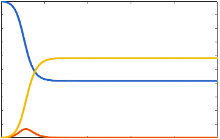?

ShowSIRModel(betaVal, gammaVal, S0Val, I0Val, tRange, totPop)

 **Reflect**. What does the phase portrait show? 

## ** Application: Building Response to Earthquakes**

When earthquakes occur, buildings undergo complex vibrations that can be modeled using systems of differential equations. 

 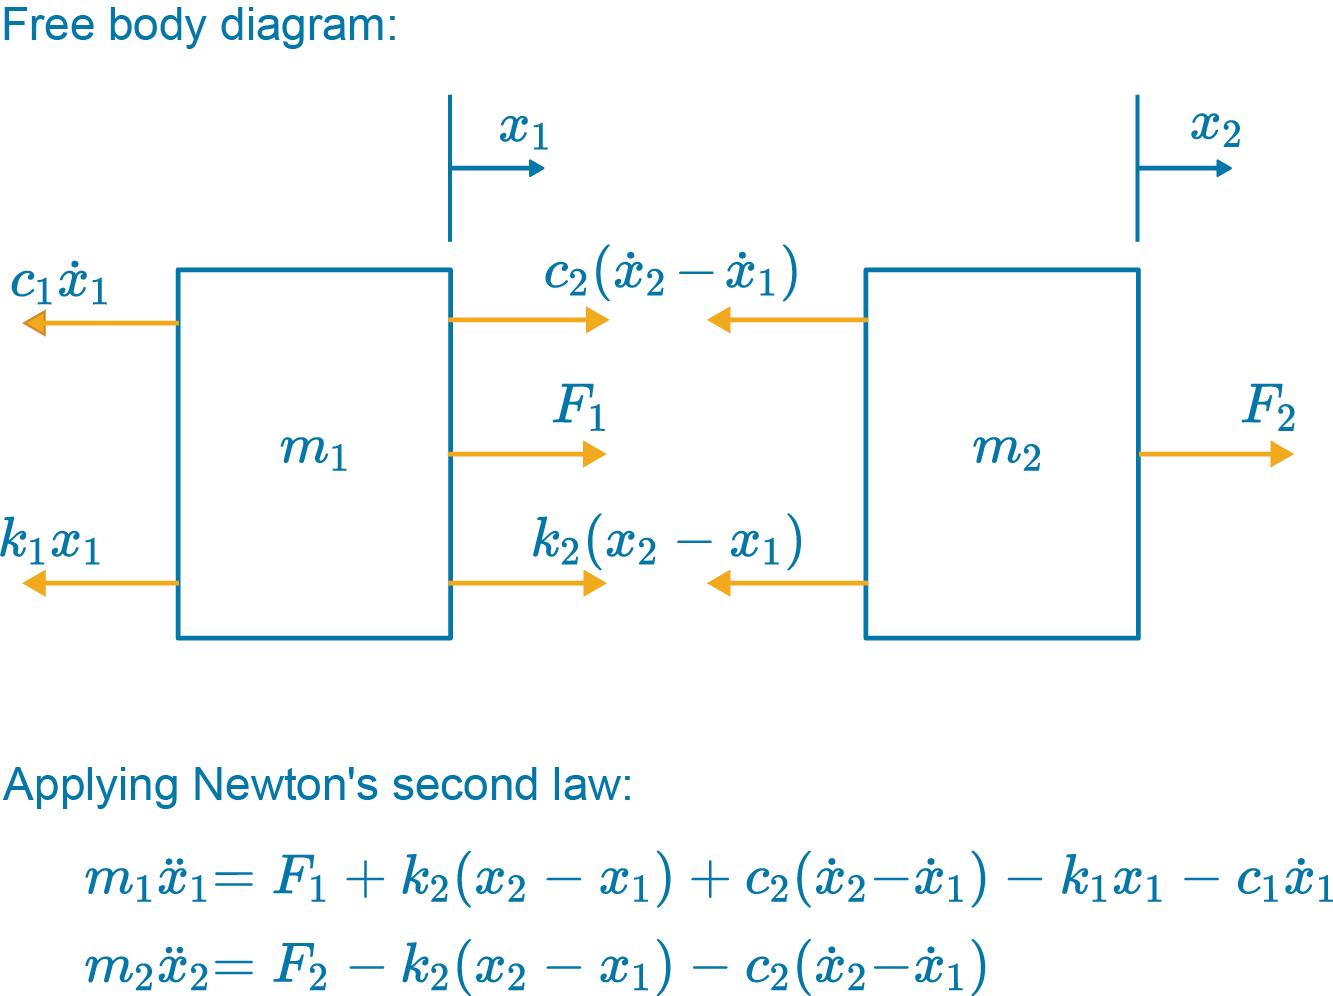

where $x_1$ and $x_2$ are the displacements of floors 1 and 2, $m_i$ are the masses, $k_i$ are the spring constants, and $c_i$ are the damping coefficients.

We can convert this second-order system, that we don't know how to solve, into a first-order system amenable to the method of eigenvectors, by introducing velocities $v_1 = \frac{dx_1}{dt}$ and $v_2 = \frac{dx_2}{dt}$. Then the system becomes:


$$\frac{dx_1}{dt} = v_1$$
                                                                     


$$\frac{dv_1}{dt} = \frac{F_1}{m_1} + \frac{k_2}{m_1}(x_2-x_1) + \frac{c_2}{m_1}\left(v_2-v_1\right)-\frac{k_1}{m_1}x_1 - \frac{c_1}{m_1}v_1$$



$$\frac{dx_2}{dt} = v_2$$
                                                                      


$$\frac{dv_2}{dt} = \frac{F_2}{m_2} - \frac{k_2}{m_2}(x_2-x_1) - \frac{c_2}{m_2}(v_2-v_1)$$
                         

clear betaVal gammaVal S0Val I0Val tRange totPop

### Undamped Building Model

 **Exercise 3.**

For simplicity, let's consider the undamped ($c_1 = c_2 = 0$) and unforced $(F_1 = F_2 = 0)$ case  with equal masses $m_1 = m_2 = m$ and spring constants $k_1 = k_2 = k$.

The system simplifies to:


$$\frac{dx_1}{dt} = v_1$$
                  


$$\frac{dv_1}{dt} = -\frac{2k}{m}x_1 + \frac{k}{m}x_2$$



$$\frac{dx_2}{dt} = v_2$$
                   


$$\frac{dv_2}{dt} = \frac{k}{m}x_1 - \frac{k}{m}x_2$$
     

Let $\omega^2 = \frac{k}{m}$ (the natural frequency squared).

a. Write the coefficient matrix $\mathbf{A}$ for this system in terms of $\omega^2$. The state vector is $\left(\matrix{x_1 \cr v_1 \cr x_2 \cr v_2 \cr}\right)$. Use `omega` for $\omega$.

syms omega
A =  [0 0 0 0; 0 0 0 0; 0 0 0 0; 0 0 0 0];  
Check3a(A);

b. The eigenvalues of this matrix are the natural frequencies of the building's vibration modes. These determine how the building responds to earthquake excitation. For $\omega^2 = 1$, find the eigenvalues. Enter them as a column vector $[\lambda_1; \,\, \lambda_2; \,\, \lambda_3; \,\, \lambda_4]$. 

Check3b([0; 0; 0; 0]);      

ShowHint = false;
if ShowHint
    if numel(A) ~= 16
        displayFormula('"You must define the matrix A first."')
    elseif Check3a(A,"nooutput")
        syms lambda
        displayFormula('"The characteristic equation is: "')
        disp(det((subs(A,omega^2,1)-lambda*eye(4))) == 0)
    else
        displayFormula('"A should not be all zeros. Please complete part a) successfully."')
    end
end

clear omega A ShowHint

### Visualize Building Vibrations

Explore how buildings respond to different initial conditions!

Set initial conditions and parameters:

omega2Val=1;
x1_0 = 0.1;

Set the time range for simulation, from 0 until

tEnd = 10;
v1_0 = 0;
x2_0 = 0;
v2_0 = 0;
tRange = [0 tEnd];
animate = false;
AnimationRate = (1)*10;

Click below to run (or re-run) the simulation!

 
ShowBuildingResponse(omega2Val, [x1_0, v1_0, x2_0, v2_0], tRange,animate,AnimationRate)
clear omega2Val x1_0 tEnd v1_0 v2_0 tRange animate AnimationRate

## Further Explorations

- Visualize more phase spaces with the [Phase Plane app](https://www.mathworks.com/matlabcentral/fileexchange/91705-phase-plane-and-slope-field-apps)

- Outbreak models for zombies, mayflies, and HIV in the [Markov Modeling](https://matlab.mathworks.com/open/github/v1?repo=MathWorks-Teaching-Resources/Applied-Linear-Algebra&project=AppliedLinAlg.prj&file=Scripts/MarkovModeling.mlx) script in the [Applied Linear Algebra](https://www.mathworks.com/matlabcentral/fileexchange/136364-applied-linear-algebra) courseware.

- Coupled-system dynamics in the [Mass-Spring-Damper](https://www.mathworks.com/matlabcentral/fileexchange/94585-mass-spring-damper-systems) courseware.

- Stability analysis in [Quantitative Analysis of ODEs](https://www.mathworks.com/matlabcentral/fileexchange/95513-qualitative-analysis-of-odes) courseware.

- The self-paced online course [Solving Ordinary Differential Equations with MATLAB](https://matlabacademy.mathworks.com/details/solving-ordinary-differential-equations-with-matlab/odes) in the Online Training Suite covers solving systems of ODEs.

[⇦ Return to the main menu](matlab:open('MainMenu.mlx'))

## Glossary

**eigenvalue:** For a matrix $M$, a number, $\lambda$, is an eigenvalue of $M$ if there exists a nonzero vector $v$ with $Mv=\lambda v$. Learn more in [Matrix Methods of Linear Algebra](https://www.mathworks.com/matlabcentral/fileexchange/94730-matrix-methods-of-linear-algebra).    Return to text ↑

**eigenvector:** For a matrix $M$, a nonzero vector $v$ is an eigenvector of $M$ if there is a number $\lambda$ such that $Mv=\lambda v$. Learn more in [Matrix Methods of Linear Algebra](https://www.mathworks.com/matlabcentral/fileexchange/94730-matrix-methods-of-linear-algebra).    Return to text ↑

**ODE:** An [ordinary differential equation](matlab:open('./Classification.mlx')), e.g. $\frac{d^2y}{dt^2} - 3t\frac{dy}{dt} + \cos(y) = t+3$, is an equation involving total derivatives of the dependent variable. Return to text ↑

**linear:** A differential equation is [linear](matlab:open('./Classification.mlx')) if it can be written in the following form: $f_n(t)\cdot \frac{d^ny}{dt^n}+ f_{n-1}(t)\cdot \frac{d^{n-1}y}{dt^{n-1}} + ...  + f_{1}(t)\frac{dy}{dt}+ f_0(t)\cdot y = g(t)$ Return to text ↑

**homogeneous:** A differential equation is [homogeneous](matlab:open('./Classification.mlx')) if all terms involve the dependent variable.  Return to text ↑

**first-order:** A differential equation is [first-order](matlab:open('./Classification.mlx')) if the highest derivative present is first-order.  Return to text ↑

**phase plane:** An n-dimensional plot where each point represents the possible state of an n-dimensional dynamical system. Learn more in [Qualitative Analysis of ODEs](https://www.mathworks.com/matlabcentral/fileexchange/95513-qualitative-analysis-of-odes).     Return to text ↑

## Local Helper Functions

If you wish to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline** using the icon   at the top right of the Live Editor pane.

% Exercise 1 functions
function PrintSystem(out)
[n,~] = size(out);
syms x y z t dx dy dt
if n == 2
    Ax = out*[x;y];
elseif n == 3
    Ax = out*[x;y;z];
end
eqn1 = Ax(1);
eqn2 = Ax(2);
displayFormula(["dx/dt == eqn1"; "dy/dt == eqn2"])
if n == 3
    eqn3 = Ax(3);
    displayFormula("dz/dt) == eqn3")
end
end

% Exercise 1 functions
function PrintSIRSystem(out)
syms S I t dS dI dt
Ax = out*[S;I];
eqn1 = Ax(1);
eqn2 = Ax(2);
displayFormula(["dS/dt == eqn1"; "dI/dt == eqn2"])
end

function M = ForceRealSolns(M)
D = eig(M);
if isreal(D(1,1))
    return
else
    M(1,2) = -M(1,2);
end
end


function out = GenerateProblem(n)
arguments
    n (1,1) double {mustBeMember(n,[2 3])}
end
out = randi(11,[n n])-6;
out = ForceRealSolns(out);
displayFormula('"Consider the following system of differential equations"')
PrintSystem(out)
end

function Check1a(matrix,A,opts)
arguments
    matrix
    A
    opts.Output (1,1) string {mustBeMember(opts.Output,["symbolic","decimal"])} = "symbolic"
end
n = size(A);
if isequal(matrix, zeros(n))
    disp("This is the default. Please enter a non-zero matrix.");
elseif size(matrix) ~= n
    disp("Incorrect. In this case, A should be a " + n(1) +"x" + n(2) + " matrix.")
elseif all(abs(matrix-A) < 1e-14)
    disp("Correct!")
    Show1a(true,A,opts.Output)
elseif n(1) == 2
    if opts.Output == "symbolic"
        disp("Incorrect. Remember to arrange the coefficients of x and y in matrix form.");
        PrintSystem(A)
    else
        disp("Incorrect. Remember to arrange the coefficients of S and I in matrix form.");
        PrintSIRSystem(A)
    end
elseif n(1) == 3
    if opts.Output == "symbolic"
        disp("Incorrect. Remember to arrange the coefficients of x, y, and z in matrix form.");
        PrintSystem(A)
    else
        disp("Incorrect. Remember that we only need to consider S and I.")
        PrintSIRSystem(A)
    end
else
    disp("Incorrect. Please try again.")
    if opts.Output == "symbolic"
        PrintSystem(A)
    else
        PrintSIRSystem(A)
    end
end
end

function Check1b(eigenvals,A,opts)
arguments
    eigenvals
    A
    opts.Output (1,1) string {mustBeMember(opts.Output,["symbolic","decimal"])} = "symbolic"
end
correctEigs = eig(sym(A));
correctEigs = double(correctEigs);
if norm(eigenvals(1) - correctEigs(1)) < 1e-4 && norm(eigenvals(2) - correctEigs(2)) < 1e-4
    disp("Correct!");
    Show1b(true,A,opts.Output)
elseif isequal(eigenvals, [0; 0])
    disp("Please enter the eigenvalues of A.");
elseif norm(eigenvals(2) - correctEigs(1)) < 1e-4 && norm(eigenvals(1) - correctEigs(2)) < 1e-4
    disp("Correct!");
    Show1b(true,A,opts.Output)
else
    syms A lambda I
    displayFormula(['"Incorrect. Solve "' "det(A - lambda*I) == 0" '" to find the eigenvalues."']);
end
end

function Check1cd(eigenvec,A,flag)
arguments
    eigenvec (2,1) double
    A (2,2) double
    flag {mustBeMember(flag,["c","d"])}
end
[V,D] = eig(A);

% Scale to allow accurate comparison
Eig1 = V(:,1)./V(2,1);
Eig2 = V(:,2)./V(2,2);
eigenvec = eigenvec./eigenvec(2);

switch flag
    case "c" % smaller or positive half-plane
        EigVecAns = Eig1;
        AltVec = Eig2;
        EigAns = D(1,1);
    case "d" % larger or negative half-plane
        EigVecAns = Eig2;
        AltVec = Eig1;
        EigAns = D(2,2);
    otherwise
        error("Unexpected flag " + flag)
end

if isequal(eigenvec, [0; 0])
    disp("This is the default. Please enter the computed eigenvector.");
elseif norm(double(eigenvec)-double(EigVecAns)) < 1e-3
    Show1cd(true,A,flag)
elseif norm(double(eigenvec)-double(AltVec)) < 1e-3
    displayFormula('"That is an eigenvector, but for the wrong eigenvalue."')
    displayFormula(['"You are trying to compute the eigenvector for "' "lambda == EigAns"])
    Show1cd(false,A,flag)
else
    displayFormula('"Incorrect."')
    Show1cd(false,A,flag)
end
end

% Exercise 2 functions
function CheckStability(answer,M)
[~,D] = eig(M);
if all(D<0)
    CorrectAnswer = "stable";
    msg = "Negative eigenvalues indicate exponential decay toward equilibrium.";
    hint = "What do negative eigenvalues mean for the long-term growth of solutions?";
elseif all(D <= 0)
    CorrectAnswer = "conditionally stable";
    msg = "Zero eigenvalues indicate marginal stability - small perturbations neither grow nor decay exponentially.";
    hint = "What do non-positive eigenvalues mean for the long-term growth of solutions?";
else
    CorrectAnswer = "unstable";
    msg = "Positive eigenvalues indicate exponential growth away from equilibrium.";
    hint = "What do positive eigenvalues mean for the long-term growth of solutions?";
end

if answer == ""
    disp("You can be more precise than this. Please select a different answer.");
elseif answer == CorrectAnswer
    disp("Correct! " + msg);
else
    disp("Not quite. " + hint);
end
end

% Exercise 3 functions
function tf = Check3a(matrix,opts)
arguments
    matrix
    opts = "showoutput"
end
tf = 0;
syms A omega
correctMatrix = [0, 1, 0, 0; -2*omega^2, 0, omega^2, 0; 0, 0, 0, 1; omega^2, 0, -omega^2, 0];
if isequal(matrix, [0, 0, 0, 0; 0, 0, 0, 0; 0, 0, 0, 0; 0, 0, 0, 0])
    msg = "This is the default. Please enter the correct matrix.";
elseif isequal(matrix, correctMatrix)
    tf = 1;
    msg = "Correct! The coefficient matrix represents the building dynamics.";
elseif ~all(size(matrix) == [4,4])
    msg = "Incorrect. Your dimensions are off. This should be a 4 x 4 matrix.";
else
    msg = "Incorrect. Remember the state vector is [x1, v1, x2, v2] and dx/dt = v, dv/dt follows from force balance.";
end
if opts == "showoutput"
    disp(msg)
    if tf
        displayFormula("A == correctMatrix")
        PrintBuildingSystem(correctMatrix)
    end
end
end

function Check3b(eigenvals)
arguments
    eigenvals double
end
syms lambda
CorrectEigs = solve(lambda^4+3*lambda^2+1==0);
if isequal(eigenvals, [0; 0; 0; 0])
    disp("This is the default. Please enter the computed eigenvalues.");
elseif length(eigenvals) == 4 && all(isreal(eigenvals*1i))
    if all(abs(sort(double(CorrectEigs*1i))-sort(eigenvals*1i))<1e-3)
        displayFormula('"Correct!"')
        eig1 = CorrectEigs(1);
        eig2 = CorrectEigs(2);
        eig1Num = round(vpa(eig1),4);
        eig2Num = round(vpa(eig2),4);
        displayFormula(['"The eigenvalues are ±"' "eig1" '" and ±"' "eig2" '", or approximately ±"' "eig1Num" '" and ±"' "eig2Num" '","'])
        displayFormula('"representing the natural frequencies of the building modes."');
    else
        disp("Incorrect.")
        disp("All eigenvalues should be imaginary, but please check your arithmetic and try again.")
    end
elseif length(eigenvals) ~= 4
    disp("Incorrect" + newline + "That is not the correct number of eigenvalues for this problem.")
elseif ~all(isreal(eigenvals*1i))
    disp("Incorrect" + newline + "The eigenvalues are all purely imaginary.")
else
    disp("Incorrect. For ω² = 1, substitute and find the characteristic polynomial.");
end
end

% Show functions
function Show1a(checked,M,output)
arguments
    checked
    M
    output
end
if output == "decimal"
    M = vpa(M);
end
if checked
    displayFormula('"The system "')
    if output == "decimal"
        syms dS dI dt S I A
        PrintSIRSystem(M)
        displayFormula(['"which can be written as "'; "[dS/dt; dI/dt] == M*[S; I]"])
    else
        syms dx dt dy x y A
        PrintSystem(M)
        displayFormula('"can be written as: "')
        displayFormula("[dx/dt; dy/dt] == M * [x; y]");
    end
    displayFormula(['"So "' "A == M"]);
end
end

function Show1b(checked,M,output)
if checked
    syms A lambda I
    MminusLambdaI = M-lambda*eye(2);
    MyCoeffs = coeffs(det(MminusLambdaI));
    while numel(MyCoeffs) < 3
        MyCoeffs = [0 MyCoeffs];
    end
    a = MyCoeffs(3);
    b = MyCoeffs(2);
    c = MyCoeffs(1);
    detEqn = det(MminusLambdaI) == 0;
    % [~,D] = eig(sym(M));
    % D1 = D(1,1);
    % D2 = D(2,2);
    displayFormula(['"To find eigenvalues, solve "' "det(A - lambda*I) == 0" '":"']);
    if output == "decimal"
        MminusLambdaI = vpa(MminusLambdaI);
    end
    displayFormula(["det(MminusLambdaI) == 0";...
        "detEqn"])
    p1 = 4*a*c;
    p2 = 2*a;
    D1 = simplify((-b+sqrt(b^2-4*a*c))/(2*a));
    D2 = simplify((-b-sqrt(b^2-4*a*c))/(2*a));
    if output == "decimal"
        b = vpa(b);
        p1 = vpa(p1);
        p2 = vpa(p2);
        D1 = vpa(D1);
        D2 = vpa(D2);
    end
    negb = -b;
    displayFormula(["lambda_1 = (negb+sqrt(b^2-p1))/(p2)" '", "' "lambda_1 == D1";...
        "lambda_2 = (negb-sqrt(b^2-p1))/(p2)" '", "' "lambda_2 == D2"])
end
end

function Show1cd(checked,M,flag)
arguments
    checked (1,1) logical
    M (2,2) double
    flag {mustBeMember(flag,["c","d"])}
end
[V,D] = eig(sym(M));
switch flag
    case "d"
        EigVecAns = V(:,1);
        EigAns = D(1,1);
    case "c"
        EigVecAns = V(:,2);
        EigAns = D(2,2);
    otherwise
        error("Unexpected flag " + flag)
end
syms A I lambda v
if checked
    displayFormula(['"For "' "lambda == EigAns" '", solve "' "(A-lambda*I)*v==0"])
    nextA = M-EigAns*eye(2);
    displayFormula("nextA*[v_1; v_2] == [0;0]")
    displayFormula("[v_1; v_2] == EigVecAns")
else
    displayFormula(['"Solve the equation "' "(A-lambda*I)*v==0"])
end
end

function [out,bDec,gDec] = GenerateSIR()
b = randi(9,1)*1e-1;
g = randi(20,1)*1e-2;
out = [0 -b; 0 b-g];
bDec = vpa(b);
gDec = vpa(g);
displayFormula(['"Let "' "beta == bDec" '" and "' "gamma = gDec" '"."'])
end

% Visualization functions
function ShowSIRModel(beta, gamma, S0, I0, tRange, TotalPopulation)
% Solve the nonlinear SIR system numerically
R0 = TotalPopulation - S0 - I0; % Initial recovered
y0 = [S0; I0; R0]/TotalPopulation;

tspan = linspace(tRange(1), tRange(2), 1000);
[t, y] = ode45(@(t,y) sirModel(t, y, beta, gamma), tspan, y0);

% Plot results
tiledlayout(1, 2);

nexttile
plot(t, y(:,1)*TotalPopulation, "-", LineWidth=2, DisplayName="Susceptible", SeriesIndex=1)
hold on
plot(t, y(:,2)*TotalPopulation, "-", LineWidth=2, DisplayName="Infected", SeriesIndex=2)
plot(t, y(:,3)*TotalPopulation, "-", LineWidth=2, DisplayName="Recovered", SeriesIndex=3)
hold off
xlabel("Time")
ylabel("Population")
title("SIR Model")
legend(Location="best")
grid on

nexttile
plot(y(:,1), y(:,2), "-", SeriesIndex="none", LineWidth=2)
xlabel("Susceptible")
ylabel("Infected")
title("Phase Portrait (S vs I)")
grid on

% Display basic reproduction number
R0 = beta / gamma ;
disp("Basic reproduction number R₀ = " +  R0);
if R0 > 1
    disp("R₀ > 1: Epidemic will occur");
elseif R0 == 1
    disp("The disease is endemic in the population.")
else
    disp("R₀ < 1: Epidemic will not occur");
end
end

function dydt = sirModel(t, y, beta, gamma)
% y is a 1x3 or 3x1 vector containing S, I, R values
S = y(1);
I = y(2);

dydt = [-beta*S*I;
    beta*S*I - gamma*I;
    gamma*I];
end

function PrintBuildingSystem(out)
syms omega x_1 v_1 x_2 v_2 dt dx_1 dv_1 dx_2 dv_2
Ax = out*[x_1; v_1; x_2; v_2];
eqn1 = Ax(1);
eqn2 = Ax(2);
eqn3 = Ax(3);
eqn4 = Ax(4);
displayFormula(["dx_1/dt == eqn1"; "dv_1/dt == eqn2"; "dx_2/dt == eqn3"; "dv_2/dt == eqn4"])
end

function ShowBuildingResponse(omega2, y0, tRange, animation,AnimStep)
% Coefficient matrix
A = [0, 1, 0, 0;
    -2*omega2, 0, omega2, 0;
    0, 0, 0, 1;
    omega2, 0, -omega2, 0];

% Solve the system
tspan = linspace(tRange(1), tRange(2), 1000);
[t, y] = ode45(@(t,y) A*y, tspan, y0');

% Plot results
tiledlayout(2, 2);

% Set fixed axis limits
x1_limits = [min(y(:,1)), max(y(:,1))]; % Adjust as necessary for x₁
x2_limits = [min(y(:,3)), max(y(:,3))]; % Adjust as necessary for x₂
v1_limits = [min(y(:,2)), max(y(:,2))]; % Adjust as necessary for v₁
v2_limits = [min(y(:,4)), max(y(:,4))]; % Adjust as necessary for v₂

if animation
    for i = 1:AnimStep:length(t)
        % First Floor Response
        nexttile(1)
        plot(t(1:i), y(1:i,1), "-", SeriesIndex=1, LineWidth=2)
        xlabel("Time")
        ylabel("x₁ (Floor 1 displacement)")
        title("First Floor Response")
        grid on
        xlim([tRange(1), tRange(2)]);
        ylim(x1_limits);

        % Second Floor Response
        nexttile(2)
        plot(t(1:i), y(1:i,3), "-", LineWidth=2, SeriesIndex=2)
        xlabel("Time")
        ylabel("x₂ (Floor 2 displacement)")
        title("Second Floor Response")
        grid on
        xlim([tRange(1), tRange(2)]);
        ylim(x2_limits);

        % Floor 1 Phase Portrait
        nexttile(3)
        plot(y(1:i,1), y(1:i,2), "-", LineWidth=2, SeriesIndex=1)
        xlabel("x₁")
        ylabel("v₁")
        title("Floor 1 Phase Portrait")
        grid on
        xlim(x1_limits);
        ylim(v1_limits);

        % Floor 2 Phase Portrait
        nexttile(4)
        plot(y(1:i,3), y(1:i,4), "-", LineWidth=2, SeriesIndex=2)
        xlabel("x₂")
        ylabel("v₂")
        title("Floor 2 Phase Portrait")
        grid on
        xlim(x2_limits);
        ylim(v2_limits);
        pause(0)
    end
else
    % Static plots
    nexttile(1)
    plot(t, y(:,1), "-", LineWidth=2, SeriesIndex=1)
    xlabel("Time")
    ylabel("x₁ (Floor 1 displacement)")
    title("First Floor Response")
    grid on
    xlim([tRange(1), tRange(2)]);
    ylim(x1_limits);

    nexttile(2)
    plot(t, y(:,3), "-", LineWidth=2, SeriesIndex=2)
    xlabel("Time")
    ylabel("x₂ (Floor 2 displacement)")
    title("Second Floor Response")
    grid on
    xlim([tRange(1), tRange(2)]);
    ylim(x2_limits);

    nexttile(3)
    plot(y(:,1), y(:,2), "-", LineWidth=2, SeriesIndex=1)
    xlabel("x₁")
    ylabel("v₁")
    title("Floor 1 Phase Portrait")
    grid on
    xlim(x1_limits);
    ylim(v1_limits);

    nexttile(4)
    plot(y(:,3), y(:,4), "-", LineWidth=2, SeriesIndex=2)
    xlabel("x₂")
    ylabel("v₂")
    title("Floor 2 Phase Portrait")
    grid on
    xlim(x2_limits);
    ylim(v2_limits);
end
end